# **Task:**   Explore deflection from a Static Load

For our single floor tower, we'll:

- Keep the ground **stationary** 

- Compute the "expected" **deflection **(X-direction) of the floor **subjected to a constant (static) load  **(X-direction)

- Then compare this prediction against the deflection produced by the **Simscape model**

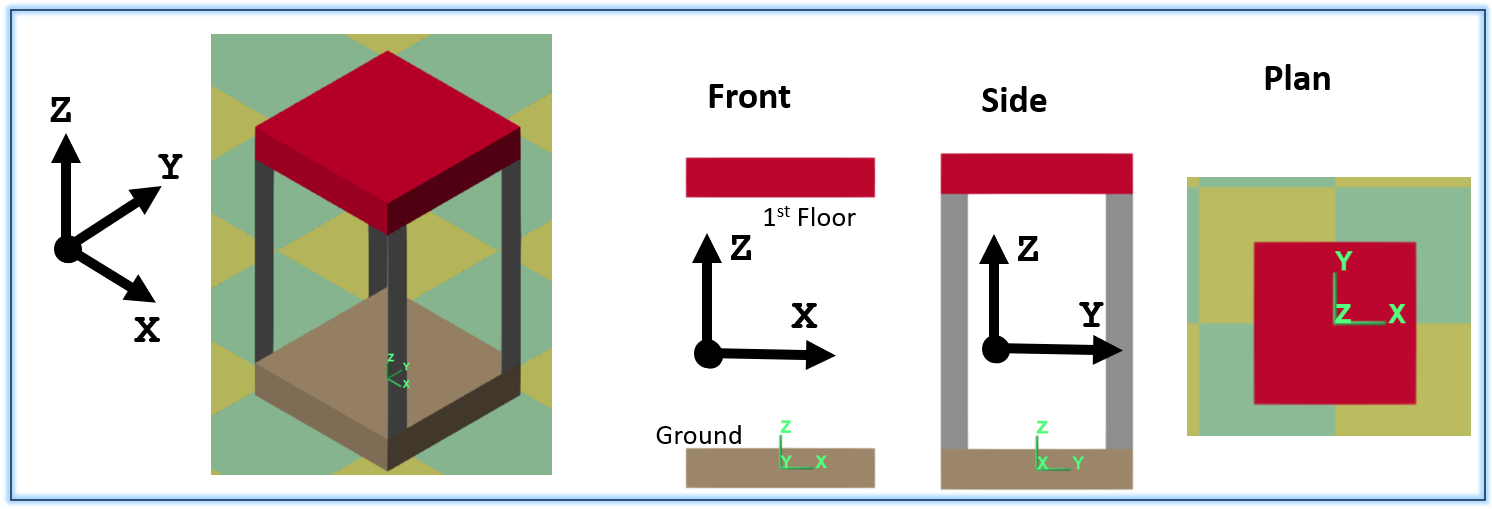

## Clear the workspace

clear

## Load the STANDARD params

See the script file [`STANDARD_params_single_tower.mlx`](matlab:  open STANDARD_params_single_tower.mlx)

STANDARD_params_single_tower

whos

  Name               Size            Bytes  Class                       Attributes

  col_OBJ            1x1               286  bh_flex_column_CLS                    
  earth_vis_OBJ      1x1                72  earth_vis_CLS                         
  floor_OBJ          1x1                32  bh_solid_floor_CLS                    
  params_dB          1x1              9169  bh_flex_tower_params_CLS              



So we have **columns** with the following properties

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 3.5000e-04
          DEPTH_y: 0.0170
         LENGTH_z: 0.1600
          density: 7900
      E_GPa_Young: 170
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 1.0000e-03
       damp_ratio: 0
         num_eles: 1
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0075
              vol: 9.5200e-07
               Ix: 1.4330e-10
               Iy: 6.0740e-14
               Kx: 30.2512
             area: 5.9500e-06


So we have **floors** with the following properties

floor_OBJ

floor_OBJ =   bh_solid_floor_CLS with properties:

        WIDTH: 0.1200
        DEPTH: 0.1200
    THICKNESS: 0.0250
         MASS: 0.5080


## Configure for this TEST

Define column damping

col_OBJ.damp_ratio = 7e-1;  %params_dB.col_damp_ratio;

## Calculate the expected deflection of 1st floor

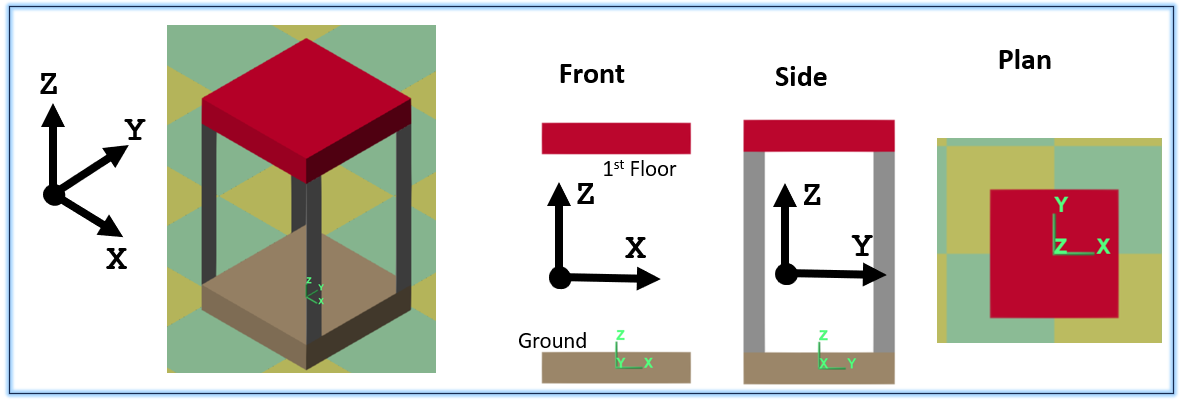

 NOTE:

- Our `col_OBJ` variable also computes equivalent stiffness for 2 different configurations

- The configuration that is likely relevant for our purposes is the `"FIXED_FIXED_WITH_SWAY"` configuration

- This computes the stiffness of the column in the X-direction, assuming the free end of the column can sway ($\theta_{\mathrm{tip}} \approx 0$)

- We have 4 columns ... so the total system stiffness is multiplied by 4

F_applied      = 5; % (N)
K_total        = 4 * col_OBJ.Kx;
disp_predicted = F_applied / K_total

disp_predicted = 0.0413

## Now compare against the Simulink model

What steady state deflection does our Simscape Multibody model produce ?

open_system("bh_single_tower_STATIC_Load_test.slx")

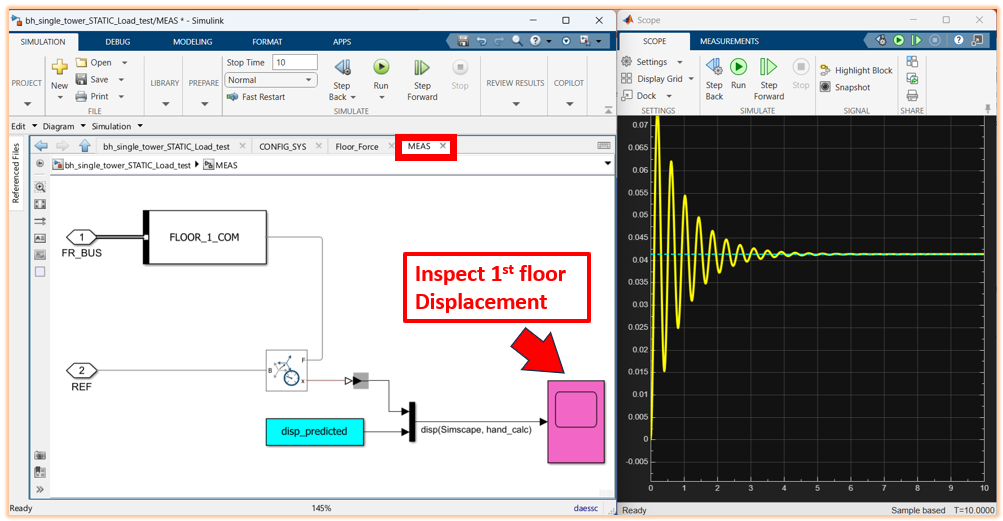

##  Pause and Ponder:

IFFF we know the stiffness of the system ... then we can use this to ***estimate*** the first resonant frequency via:

- $\omega_n =\sqrt{\frac{k}{m}}$    (rad/sec)

w_expected = sqrt( K_total/floor_OBJ.MASS );

array2table([w_expected, (w_expected/(2*pi))], "VariableNames",["w_radpsec", "f_Hz"])

ans = 1×2 table
    w_radpsec     f_Hz 
    _________    ______

     15.434      2.4563

	Get insights using Copilot


We'll do an impact test **NEXT**  .... and extract the actual resonant frequency using concepts from **Experimental Modal Analysis (EMA).**